# Mixed-mesh Finite Volume Method 

Supplemental code to the article *Dostal J., Havlena V., Mixed Mesh Finite Volume Method for 1D Hyperbolic Systems with Application to Plug-flow Heat Exchangers, Mathematics, 2021. *

Compare MMFVM method to regular FVM in a low-dimensional heat exchanger simulation scenario.

clearvars
close all

iFigInputs = 21;
iFigStates = 22; 
iFigOutputs = 23;

## HX Properties

### Dimensions

Di_tube = 0.007; %[m] inner tube dimension
L_tubes_tot = 15; %[m] total tube length (influences water temp. dynamics)

### Thermal inertia of the body

Influences air temperature dynamics

C_hx_body = 2.2592e+03; %[J/K]

### Water-to-body heat transfer coefficient model

Fitted exponential model to measured FCU data

% par = [a,b,fw0_kgh]
%         / fw_kgh < fw0_kgh; UA = a*fw0_kgh^b = const.
% UAwb = |
%         \ fw_kgh > fw0_kgh; UA = a*fw_kgh^b
UAwb_parameters = [4.3134e+01 2.9167e-01 3];
UAwb_model = @(fw_kgh) UAwb_parameters(1)*...
    (fw_kgh + ...
    (fw_kgh < UAwb_parameters(3)).*(UAwb_parameters(3) - fw_kgh))...
    .^UAwb_parameters(2); %[W/K]

### Body-to-air heat transfer coefficient model

Fitted 2nd order polynomial model to measured FCU data

UAba_parameters = [2.1896e+04  -3.1323e+03   2.6088e+02];
UAba_model = @(fa_m3h) UAba_parameters(1)*fa_m3h.*fa_m3h/(3600^2) + ...
    UAba_parameters(2)*fa_m3h/3600 + UAba_parameters(3); % [W/K]

### Other constants

% Water properties
rho_w = 1000; %[kg/m3]
cp_w = 4180; %[J/kg/K] 

V_water = pi*(Di_tube/2)^2 * L_tubes_tot; %[m3] volume in tubes
m_hx_liquid = rho_w*V_water; %[kg] mass of water in tubes

## Define simulation inputs

% Simulation length 
sim_time = 200; %[s]

% Sampling time
Ts_u = 0.01; %[s] % input sampling
Ts_y = 2; % [s] output sampling
t = 0:Ts_u:sim_time;

% Water mass flow (m_dot) step
m_dot = generate_step_input(t,100/3600, [50,201], 1/3600*[75,150]); %[kg/s] water

% Inlet air temperature (Tai) step
Tai = generate_ramp_input(t,30, [350, 400], [30, 5]); %[C] air

% Inlet water temperature (Twi) step
Twi = generate_step_input(t,60, 100, 70); %[C] air 

% Air volumetric flow (V_dot) step
V_dot = generate_ramp_input(t,450/3600, [160 170 400], 1/3600*[450 250 250]); %[C] air


#### Plot inputs

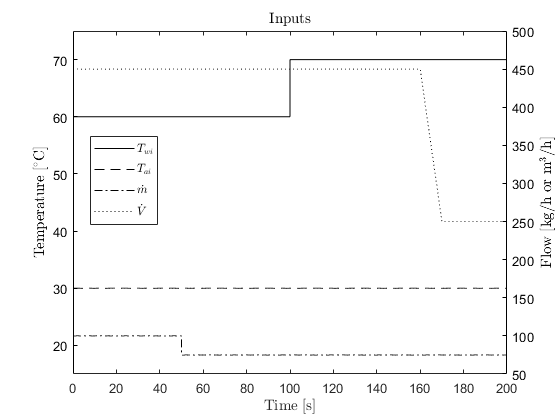

%{-
figure(iFigInputs); clf; set(gcf,'Name','Inputs');
yyaxis left
h = plot(t,Twi,t,Tai);
h(1).LineStyle = '-'; h(1).Color = 'k';
h(2).LineStyle = '--'; h(2).Color = 'k';
ylabel('Temperature [$^\circ$C]','Interpreter','Latex');
ylim([15, 75]);

yyaxis right
h = plot(t,m_dot*3600,t,V_dot*3600);
h(1).LineStyle = '-.'; h(1).Color = 'k';
h(2).LineStyle = ':'; h(2).Color = 'k';
ylabel('Flow [kg/h or m$^3$/h]','Interpreter','Latex');
l = legend('$T_{wi}$','$T_{ai}$','$\dot{m}$','$\dot{V}$','Location','best');
l.Interpreter = 'Latex';
l.Position = [0.1687    0.4650    0.1057    0.2119];
xlabel('Time [s]','Interpreter','Latex');
ylim([50, 500]);
drawnow
title('Inputs','FontWeight','normal','Interpreter','Latex');

ax = gca;
ax.YAxis(1).Color = 'k';
ax.YAxis(2).Color = 'k';

%}

## Prepare plotting

### State line plotting

The state of nodes in equidistantly-spaced positions is plotted. To avoid interpolation ensure that number of nodes *Nx* is and odd multiple of the number of plot lines *n_plot.*

n_plot = 4; 

### Initialize plots

h(1) = figure(iFigStates); h(1).Name = 'States'; clf(h(1));
h(2) = figure(iFigOutputs); h(2).Name = 'Outputs'; clf(h(2));

legStr = []; iLeg = 0;
hLegOut = [];
hLegState = [];

## Simulate TRUE solution (FVM with a high number of nodes)

### Setup

% Number of nodes
k = 125;
Nw = (2*k+1)*n_plot; % number of liquid nodes (odd multiple of n_plot to eliminate interpolation)
Nwb = 1; % number of liquid nodes per one body node

% Create a simulation object
hx = hxModels.FVM;

% Flux limiter ('Van_Leer', 'superbee', 'smart', 'mc', 'minmod', 'Koren',
% 'CHARM', 'Osher', 'UMIST','ospre','HCUS','HQUICK','van_Albada_1','van_Albada_2',
% 'mg','Sweby','fo')
hx.flux_limiter = 'HCUS';

% Simulation mode ('continuous', 'discrete')
hx.simulation_mode = 'continuous';

% Integration method ('RK1','RK2','RK2e','RK4')
hx.integration_method = 'RK4';

% Output sampling 
hx.Ts_y = 0.2;
hx.Ts_y_max = (m_hx_liquid/Nw)/min(m_dot); %ensure stability (CFL condition)

% Heat exchange coefficients
hx.UAba_model = UAba_model;
hx.UAwb_model = UAwb_model;

% Other constants
hx.Cb = C_hx_body;
hx.mw = m_hx_liquid;
hx.Nw = Nw; 
hx.Nwb = Nwb;

### Initial conditions

All water and body nodes are at air temperature.

hx.Tw0 = Tai(1)*ones(Nw,1);
hx.Tb0 = Tai(1)*ones(Nw/Nwb,1);

### Steady state output

%{
hx.run_ss(m_dot, V_dot, Twi, Tai,Ts_u);
opt = {'k--','LineWidth',1};
figure(iFigOutputs); hx.plot_ss_outputs(opt{:});
figure(iFigStates); hx.plot_ss_states(opt{:});
%}

### Run simulation

hx.run(m_dot, V_dot, Twi, Tai,Ts_u);

## Started simulation of "FVM" model 
	Done. Time elapsed 3.18 s.


### Plot results

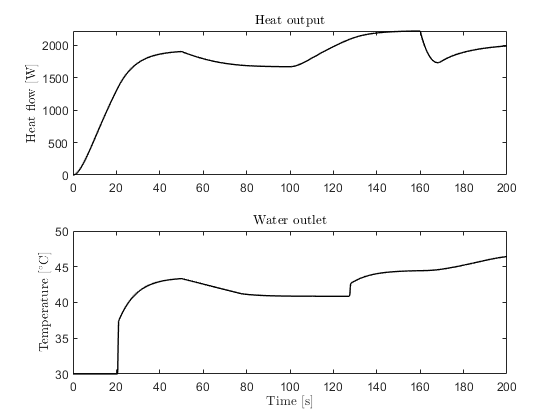

opt = {'k-','LineWidth',1};
iLeg = iLeg + 1;
legStr{iLeg} = ['True (FVM ',hx.flux_limiter,' N=', num2str(Nw),')'];

figure(iFigOutputs); hLegOut(iLeg) = hx.plot_outputs(opt{:});

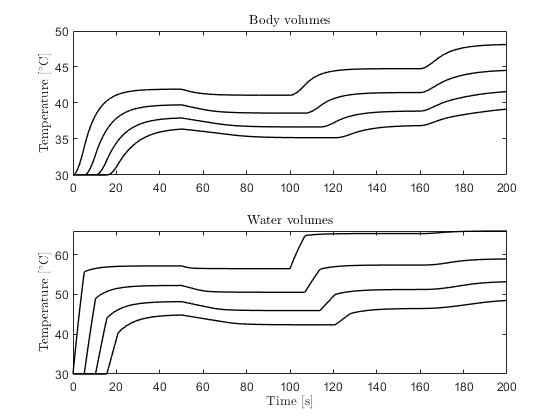

figure(iFigStates); hLegState(iLeg) = hx.plot_states(opt{:});

## Simulate Finite Volume Method (FVM) 

### Setup

% Number of nodes
k = 0;
Nw = (2*k+1)*n_plot; % number of liquid nodes
Nwb = 1; % number of liquid nodes per one body node

% Create a simulation object
hx = hxModels.FVM;

% Flux limiter ('Van_Leer', 'superbee', 'smart', 'mc', 'minmod', 'Koren',
% 'CHARM', 'Osher', 'UMIST','ospre','HCUS','HQUICK','van_Albada_1','van_Albada_2',
% 'mg','Sweby','fo')
hx.flux_limiter = 'HCUS';

% Simulation mode ('continuous', 'discrete')
hx.simulation_mode = 'continuous';

% Integration method ('RK1','RK2','RK2e','RK4')
hx.integration_method = 'RK4';

% Output sampling 
hx.Ts_y = Ts_y;
hx.Ts_y_max = (m_hx_liquid/Nw)/min(m_dot); %ensure stability (CFL condition)

% Heat exchange coefficients
hx.UAba_model = UAba_model;
hx.UAwb_model = UAwb_model;

% Other constants
hx.Cb = C_hx_body;
hx.mw = m_hx_liquid;
hx.Nw = Nw; 
hx.Nwb = Nwb;

### Initial conditions

All water and body nodes are at air temperature.

hx.Tw0 = Tai(1)*ones(Nw,1);
hx.Tb0 = Tai(1)*ones(Nw/Nwb,1);

### Steady state output

%{
hx.run_ss(m_dot, V_dot, Twi, Tai,Ts_u);
opt = {'k--','LineWidth',1};
figure(iFigOutputs); hx.plot_ss_outputs(opt{:});
figure(iFigStates); hx.plot_ss_states(opt{:});
%}

### Run simulation

hx.run(m_dot, V_dot, Twi, Tai,Ts_u);

## Started simulation of "FVM" model 
	Done. Time elapsed 0.10 s.


### Plot results

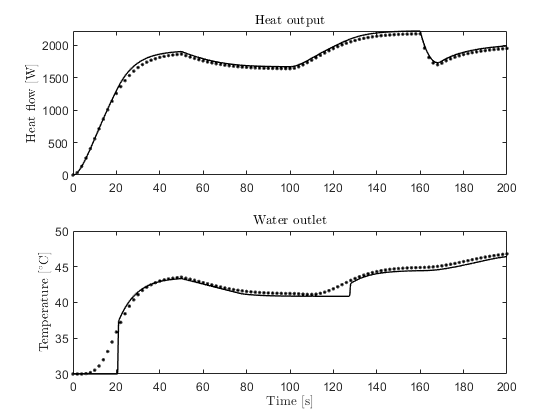

opt = {'k.','LineWidth',1};
iLeg = iLeg + 1;
legStr{iLeg} = ['FVM ',hx.flux_limiter,' N=', num2str(Nw)];

figure(iFigOutputs); hLegOut(iLeg) = hx.plot_outputs(opt{:});

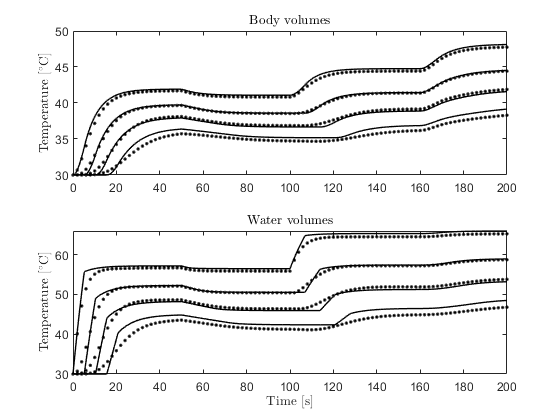

figure(iFigStates); hLegState(iLeg) = hx.plot_states(opt{:});

### Results with different limiter?

%{
hx.flux_limiter = 'HQUICK';
hx.run(m_dot, V_dot, Twi, Tai,Ts_u);

opt = {'g-','LineWidth',1};
figure(iFigOutputs); hx.plot_outputs(opt{:});
figure(iFigStates); hx.plot_states(opt{:});
%}

## Simulate Mixed Mesh (Advected) Finite Volume Method (MMFVM)

### Setup

The number of nodes and all other constants are equal to the FVM for comparison

% Number of nodes - 
% k = 0;
% Nw = (2*k+1)*n_plot; % number of liquid nodes
% Nwb = 1; % number of liquid nodes per one body node

% Create a simulation object
hx = hxModels.MMFVM;

% Simulation mode ('continuous', 'discrete')
hx.simulation_mode = 'continuous';

% Output sampling mode ('output', 'equidistant')
% define 'output' to get output samples at state jumps (no interpolation)
% define 'equidistant' to get output samples equidistant in time (interpolation errors might occurs)
hx.sampling_mode = 'output'; 

% Output sampling 
hx.Ts_y = Ts_y;
m_dot_min = 15/3600; %[kg/s] minimum allowable flow for MMFVM
hx.Ts_y_max = (m_hx_liquid/Nw)/m_dot_min; % ensure CFL

% Heat exchange coefficients
hx.UAba_model = UAba_model;
hx.UAwb_model = UAwb_model;

% Other constants
hx.Cb = C_hx_body;
hx.mw = m_hx_liquid;
hx.Nw = Nw; 
hx.Nwb = Nwb;

### Initial conditions

All water and body nodes are at air temperature.

hx.Tw0 = Tai(1)*ones(Nw,1);
hx.Tb0 = Tai(1)*ones(Nw/Nwb,1);

### Run simulation

hx.run(m_dot, V_dot, Twi, Tai,Ts_u);

## Started simulation of "MMFVM" model 
	Done. Time elapsed 0.41 s.


### Plot results

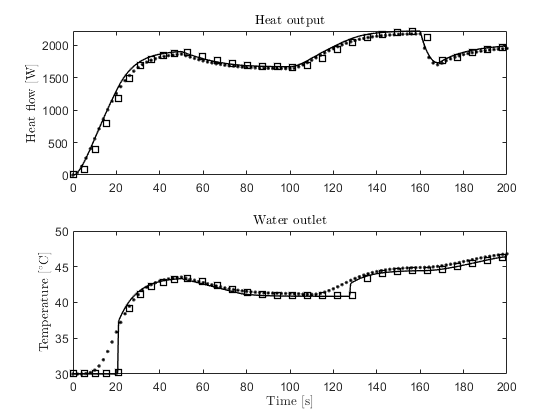

opt = {'k.','LineWidth',1,'Marker','s'};
iLeg = iLeg + 1;
legStr{iLeg} = ['MMFVM N=', num2str(Nw)];

figure(iFigOutputs); hLegOut(iLeg) = hx.plot_outputs(opt{:});

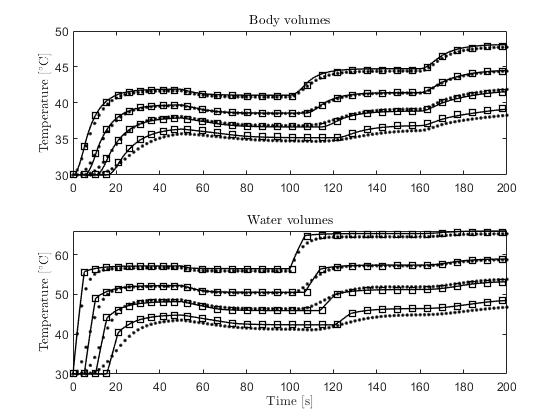

figure(iFigStates); hLegState(iLeg) = hx.plot_states(opt{:});

## Post-plot processing

### Add legend

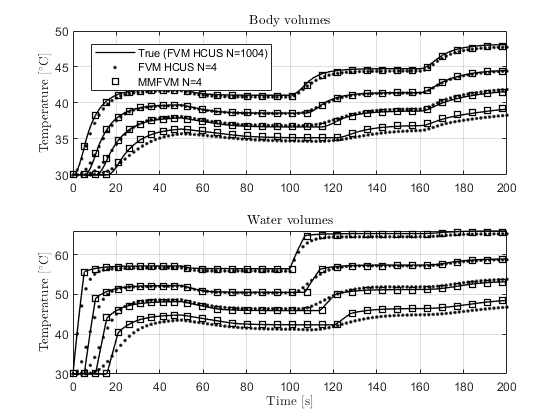

% State figure
ax = findobj(iFigStates,'Type','axes');
axes(ax(1));
legend(hLegState,legStr,'Location','best');
grid on
axes(ax(2));
grid on

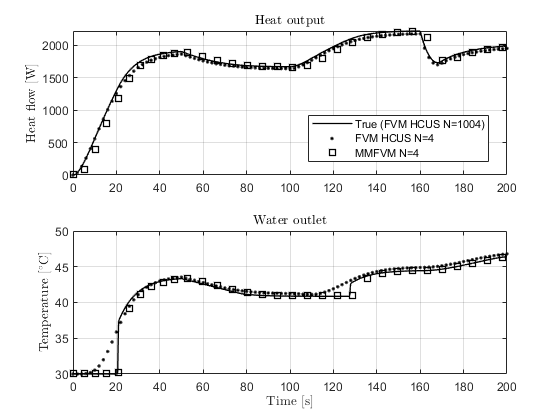


% Output figure
ax = findobj(iFigOutputs,'Type','axes');
axes(ax(1));
legend(hLegOut,legStr,'Location','best');
grid on
axes(ax(2));
grid on

#### Helper functions

### Generate gauss-shaped input sequence

function u = generate_gauss(t, mu_t, sigma) %#ok<DEFNU>
f = @(t) 1/(sigma * sqrt(2*pi)) * exp(-1/2*((t-mu_t)/sigma).^2);
u = generate_step_input(t,0,t,f(t)/f(mu_t));
end

### Generate step input sequence

function u = generate_step_input(t, init_value, t_steps, step_values)
if length(t_steps) > length(step_values)
    error('Dimension of ''steps'' smaller or equal to the dim. of ''values''');
end
u = ones(size(t))*init_value;
for i = 1:numel(t)
    idx = find(t(i) >= t_steps,1,'last');
    if ~isempty(idx)
        u(i) = step_values(idx);
    end
end
end

### Generate ramp input sequence

function u = generate_ramp_input(t, init_value, t_steps, step_values)
if length(t_steps) > length(step_values)
    error('Dimension of ''steps'' smaller or equal to the dim. of ''values''');
end
u = interp1(t_steps(:),step_values(:),t,'linear',init_value);
end
